#### Nonlinear Approximation

The physics of this problem produces the following two equations:


$$\matrix{
(M+m)\ddot{x}+ml\cos{\theta}\ddot{\theta} &=&ml\dot{\theta}^2\sin{\theta} - b\dot{x} +F\cr
ml\cos{\theta}\ddot{x} +(I+ml^2)\ddot{\theta} &=& -mgl\sin{\theta}
}$$


which can be reduced to


$$\matrix{
A\ddot{x} + B\ddot{\theta} &=& S \cr
C\ddot{x} +D\ddot{\theta} &=& T
} $$


where:


$$\matrix{
A &=& M+m\cr
B &=&ml\cos{\theta} \cr
C &=&ml\cos{\theta} \cr
D & = &I+ml^2 \cr
S &=& ml\dot{\theta}^2 \sin{\theta} -b\dot{x} + F\cr
T &=& -mgl\sin{\theta}
}$$


Given these variables,


$$\matrix{
\ddot{x} &=& \frac{SD-BT}{AD-BC} \cr
\ddot{\theta} &=& \frac{AT-CS}{AD-BC}
}$$


Similar to the Euler Approximation, the nonlinear approximation computes $dV$ for each timestep and adds it to the state variable $V$ computed for the previous timestep. For timestep $t$ the calculation is:


$$V_t = V_{t-1} + dV_tdt$$


where: $dV_t = \pmatrix{
\dot{x_{t-1} \cr
\ddot{x_t} \cr
\dot{\theta_{t-1}\cr
\ddot{\theta_t} \cr
}$ and $\ddot{x}$ and $\ddot{\theta}$ are calculated from the constants above which are in turn calculated from the state variables from the previous timestep.

The project document specified no control system for the nonlinear system so the simulations in the next section do not contain any.

#### Simulations

With no force applied to the cart and the pendulum initially in the upright position, the system is in equilibrium: nothing moves. The figure below shows no change in the $x$ position of the cart and the $\phi$ angle of the pendulum over the 20 seconds of the simulation. This illustrates Newton's first law: a system in equilibrium remains in equilibrium until an external force acts on it. This is an unstable equilibrium as even the slightest force or off-vertical pendulum position will move the system to a different equilibrium.

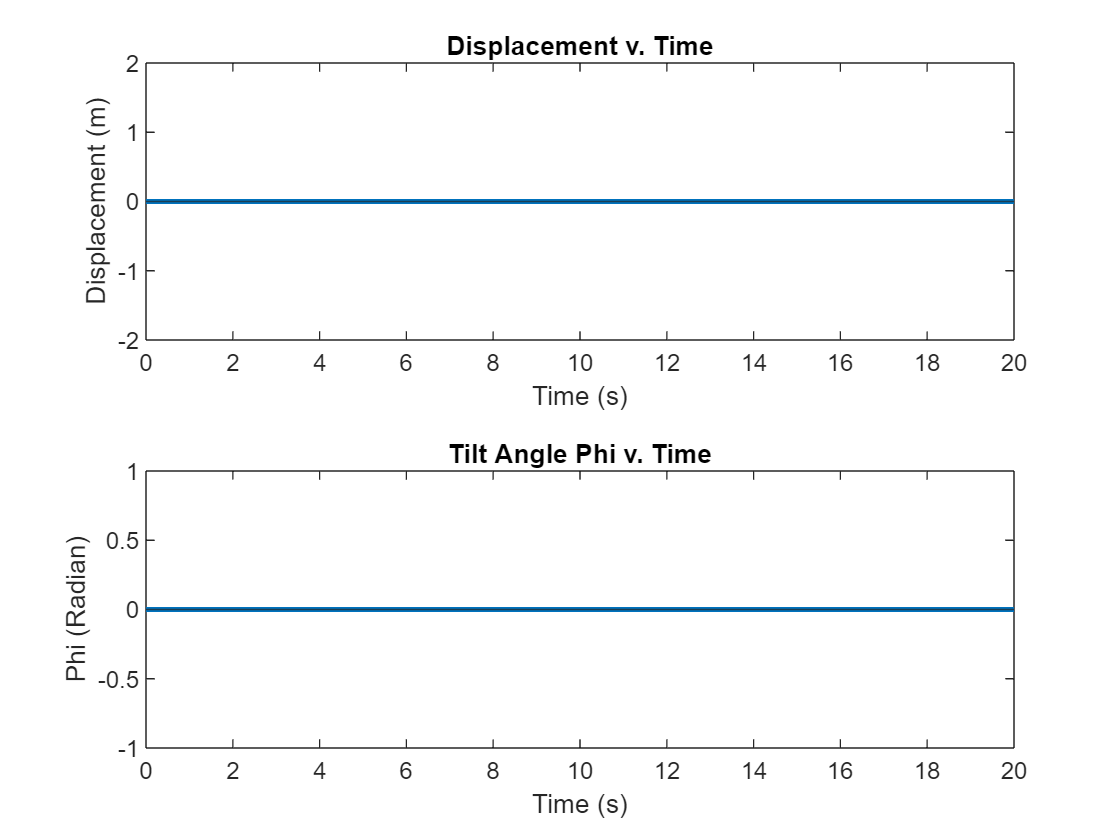

V0 = [0;0;0;0];
time_t = [0:0.001:20];

force = 0;
descr = sprintf('Forece: %.2f', force);

IP = InvertedPendulum();

sr = IP.nonlinear_method(V0,force, time=time_t, description=descr);

tiledlayout(2,1)
nexttile
sr.plotX
ylim([-2 2])
nexttile
sr.plotPhi

If the pendulum is initially tilted a little bit left or right, it is off-balance and gravity accelerates the pendulum downward. The pendulum then enters into a damped harmonic motion, swinging clockwise and counterclockwise as the bottom panel in the figure below shows.

In this case, the pendulum swings down in a clockwise direction, at the bottom of its arc, it pulls the cart to the negative $x$ dircetion. As the pendulum swings back, the cart oscillates in the positive direction. After about 15 seconds, the cart oscillates around the origin.

Although difficult to see, the amplitude of the  angular displacement $\phi$ is gradually decreasing. This is due to the friction that the cart encounters in its motion. The friction gradually bleeds energy from the system, which dampens the cart's motion which in turn dampens the pedulum's motion.

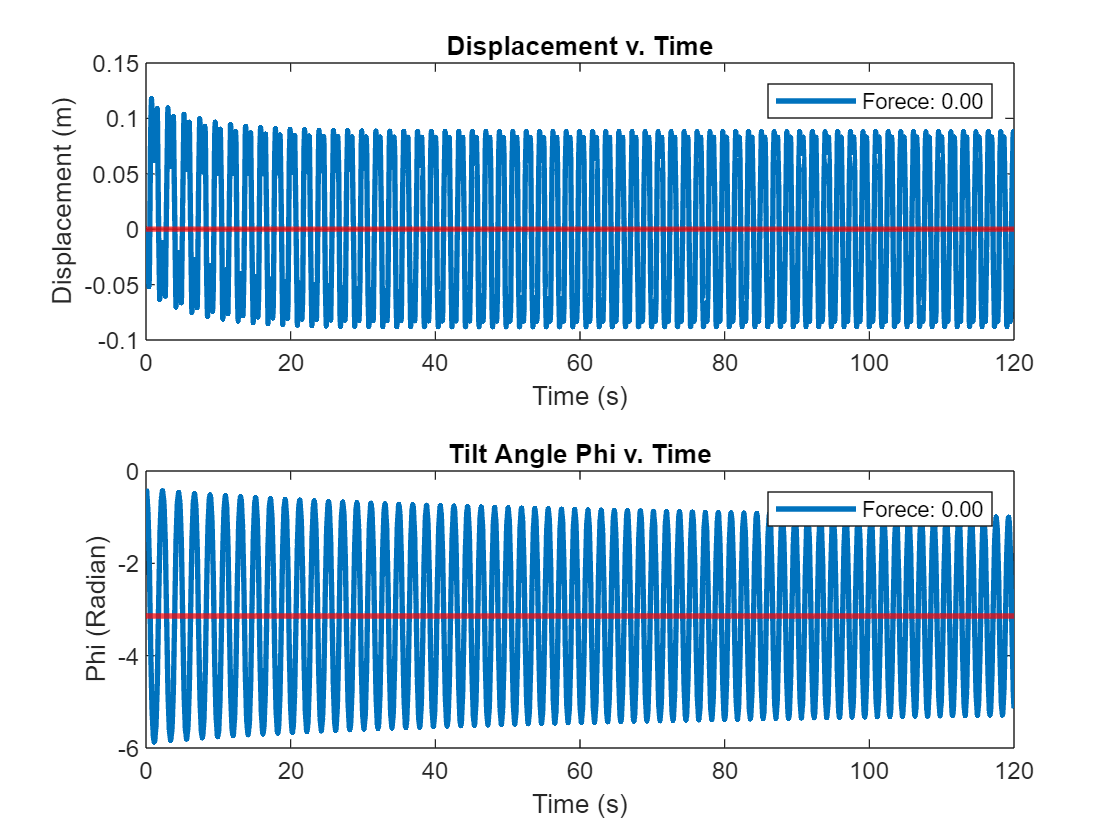

V0 = [0;0;-pi/8;0];
time_t = [0:0.001:120];
force = 0;
descr = sprintf('Forece: %.2f', force);
IP = InvertedPendulum();

sr = IP.nonlinear_method(V0,force, time=time_t, description=descr);

tiledlayout(2,1)
nexttile

sr.plotX
yline(0, LineWidth=2, color='red', HandleVisibility='off')
legend
nexttile
sr.plotPhi
yline(-pi, LineWidth=2, color='red', HandleVisibility='off')
legend

#### The Damping Effect of Friction

The nonlinear approximation reaches equilibrium in less time when the resistance (the factor $b$) is increased. The figure below shows such a result. After about 40 seconds, the pendulum settles down to its equilibrium position of $-\pi$, that is, straight down from the vertical position. In this simulation, since the force is set to zero, the inital position of the pendulum needed to be a bit  'off plumb' in order to get any motion in the system. In this simulation, we chose $\frac{\pi}{8}$ or 22.5 degrees tilted left as the pendulum's starting position.

The motion of the pendulum, which is no longer inverted, induces a force and therefore an acceleration and horizontal motion on the cart, which the bottom panel below illustrates. The cart oscillates horizontally with an initial amplitude of about 100 cm, eventually coming to rest at its starting point.

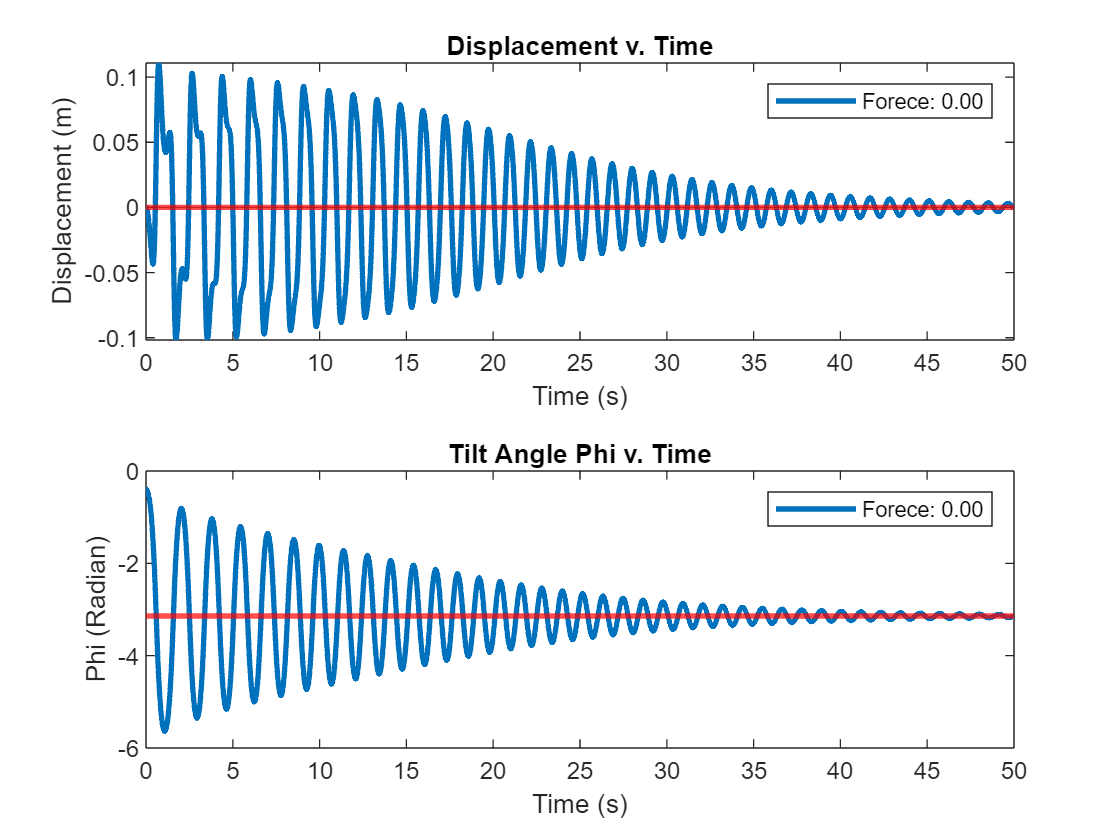

V0 = [0;0;-pi/8;0];
time_t = [0:0.005:50];
force = 0;
descr = sprintf('Forece: %.2f', force);

IP = InvertedPendulum("b",1.0);

sr1 = IP.nonlinear_method(V0, force, time=time_t, description=descr);

tiledlayout(2,1)
nexttile
sr1.plotX
yline(0, LineWidth=2, color='red', HandleVisibility='off')
legend
nexttile
sr1.plotPhi
yline(-pi, LineWidth=2, color='red', HandleVisibility='off')
legend;
hold off

This figure compares the two carts experiencing low and high friction. It is clear from the chart the high friction cart comes to equilibrium much more quickly than the low friction cart.

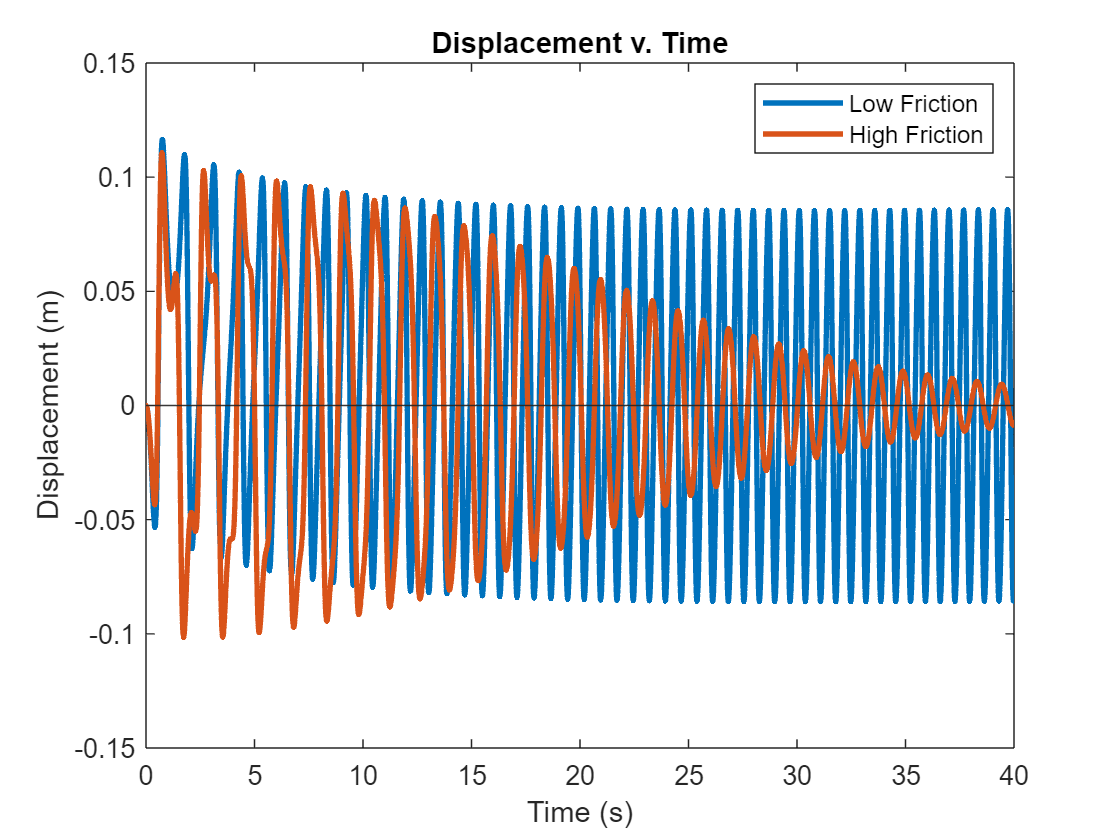

clf
V0 = [0;0;-pi/8;0];
time_t = [0:0.005:40];
force = 0;
IP = InvertedPendulum();

sr = IP.nonlinear_method(V0,force, time=time_t, description='Low Friction');
IP1 = InvertedPendulum("b",1.0);

sr1 = IP1.nonlinear_method(V0, force, time=time_t, description='High Friction');
sr.plotX
hold on
sr1.plotX
hold off

legend

#### Effect of Applied Force

A force applied to the cart will accelerate the system in the positive $x$ direction for the duration of the simulation. Eventually the motion of the pendulum settles to its' equilibrium postion ($-\pi$, i.e., down) and the cart keeps accelerating rightward. The figure below shows the results of applying  a 1 $N$ force to a cart with a resistance factor of $b=1 \frac{kg}{s}$ (10 $\times$ greater than the default). After 30 seconds the pendulum comes to rest but the cart keeps on moving.

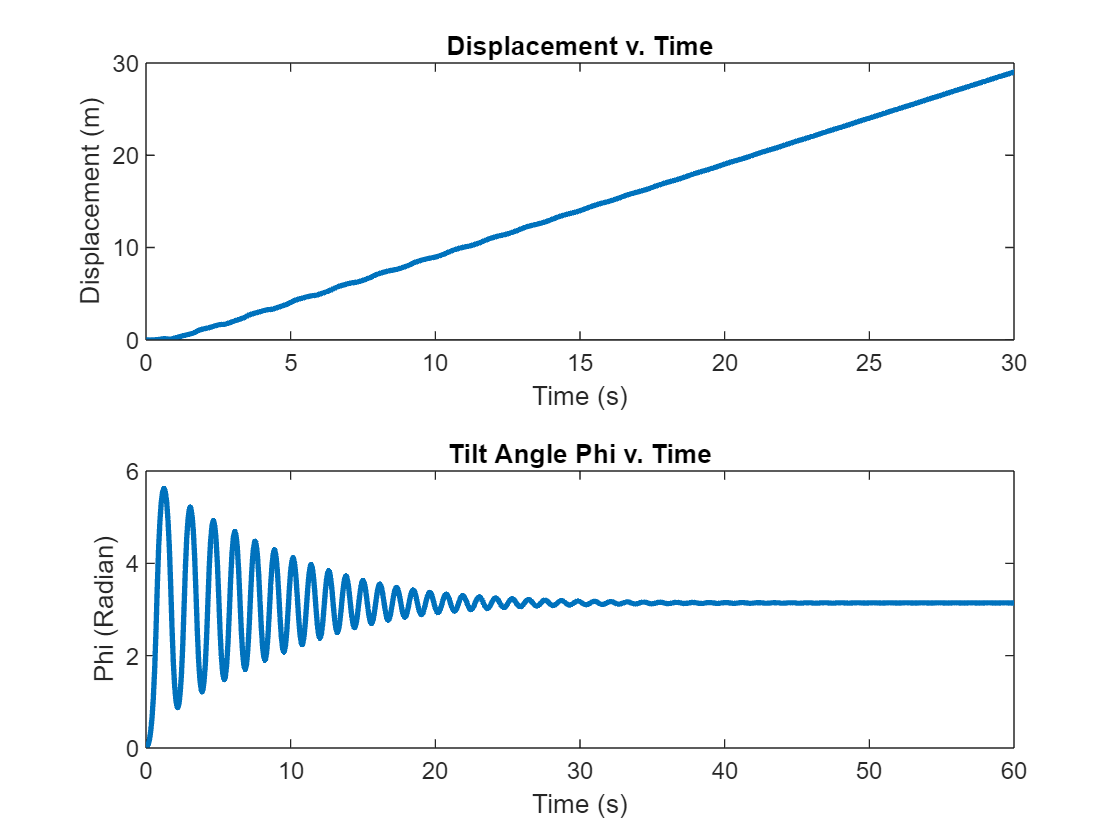

ans = 0.9999

V0 = [0;-pi/8;0;0];
time_t = [0:0.001:60];

force = 1;
descr = sprintf('Forece: %.2f', force);

IP = InvertedPendulum(b=1.0);

sr = IP.nonlinear_method(V0,force, time=time_t, description=descr);
clf
tiledlayout(2,1)
nexttile
sr.plotX
xlim([0,30])
%ylim([-2 2])
nexttile
sr.plotPhi